## Gauss mixture initialized by kmeans

close all; clear;
d = 2;
k = 3;
n = 500;
[X,label] = mixGaussRnd(d,k,n);
init = kmeans(X,k);
[z,model,llh] = mixGaussEm(X,init);

EM for Gaussian mixture: running ... 


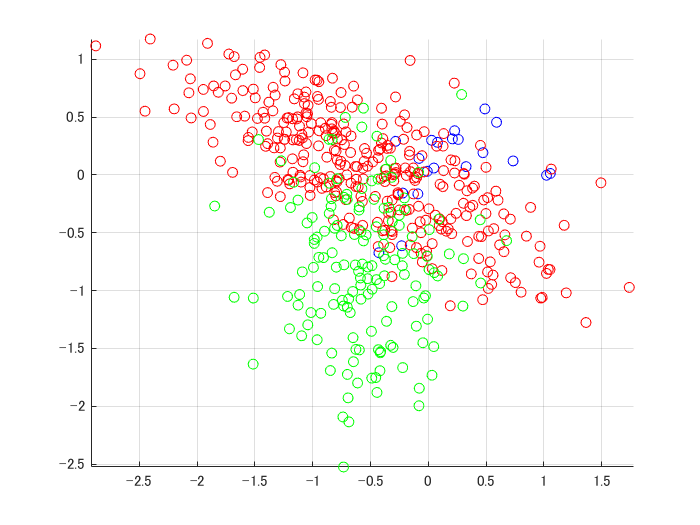

plotClass(X,label);

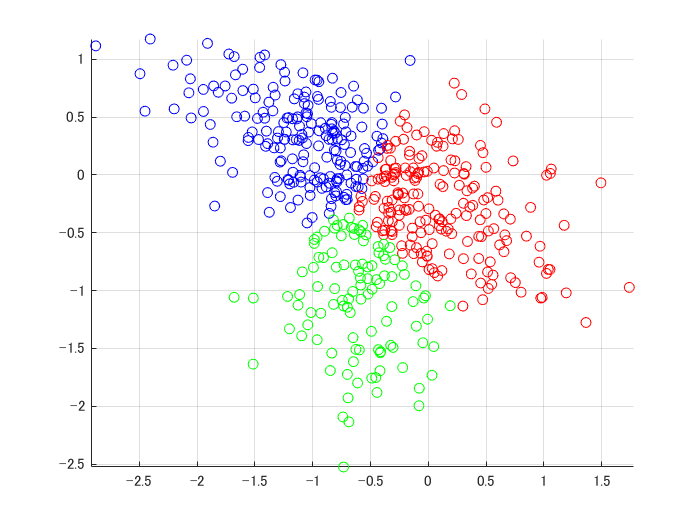

figure;
plotClass(X,init);

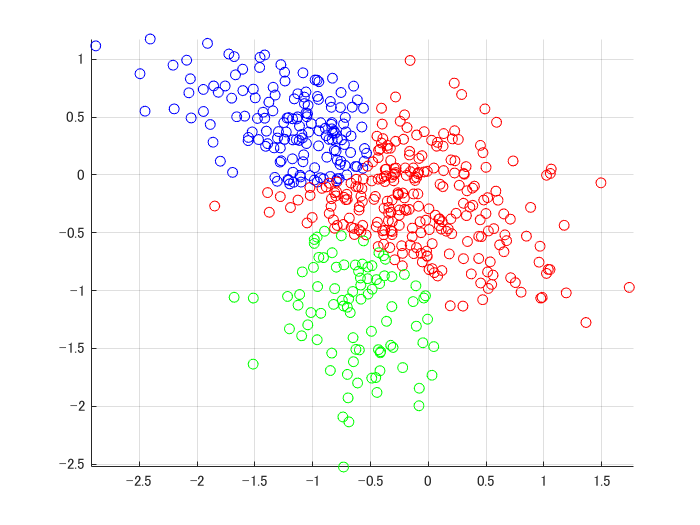

figure;
plotClass(X,z);

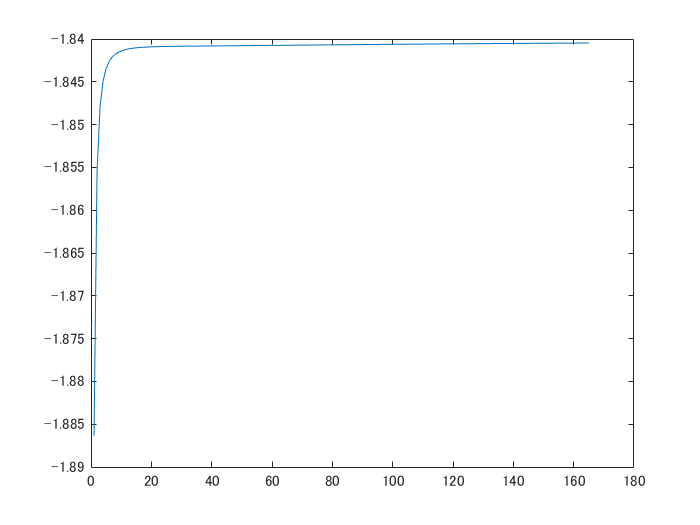

figure;
plot(llh);